# **HW15 [ALL CORRECT]**

## Q1 [CORRECT]

### True value

v = @(t) (2.*t) ./ sqrt(1 + t.^2)
dv = @(t) 2 ./ (1 + t.^2).^(3/2)
ttest = 5;
Dtrue = dv(ttest)

### Approximation: Richardson Extrapolation, $\mathit{\mathbf{O}}\left({\mathit{\mathbf{h}}}^4 \right)$

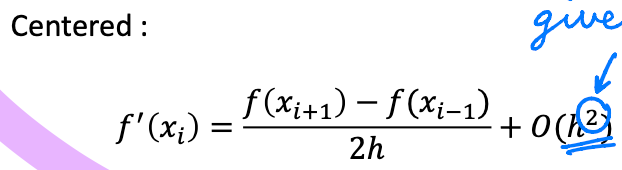

*Use centered differences by default if not specified.*

h1 = 0.5; h2 = 0.25;
ch1 = (v(ttest+h1) - v(ttest-h1)) / (2*h1);
ch2 = (v(ttest+h2) - v(ttest-h2)) / (2*h2);
Dapprox = (4/3)*ch2 - (1/3)*ch1

## Q2 [CORRECT]

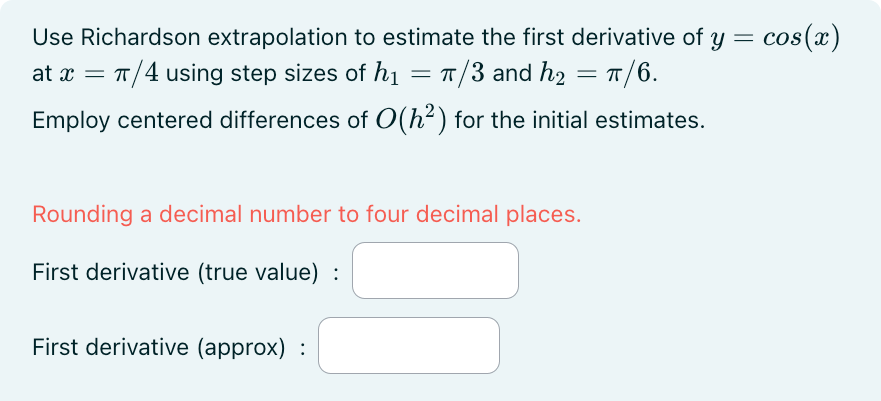

"Employ centered differences of $O\left(h^2 \right)$ for the initial estimates" = "Use the $O\left(h^4 \right)$ formula of Richardson Expansion"

f = @(x) cos(x);
dx = @(x) -sin(x); % 1st derivative of cos(x)
xtest = pi/4;
h1 = pi/3;
h2 = pi/6;
Dtrue = dx(xtest)
ch1 = (f(xtest+h1) - f(xtest-h1)) / (2*h1);
ch2 = (f(xtest+h2) - f(xtest-h2)) / (2*h2);
Dapprox = (4/3)*ch2 - (1/3)*ch1

## Q3 [CORRECT]

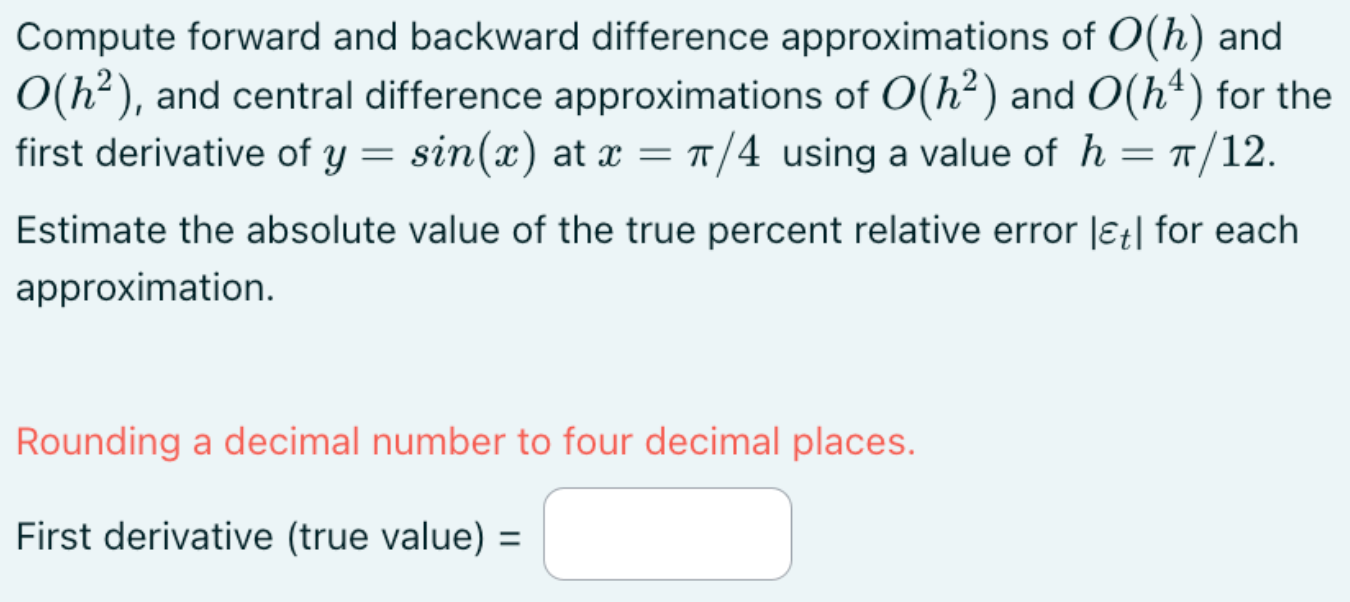    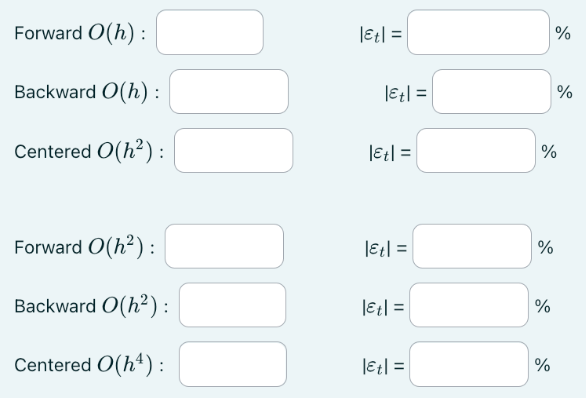

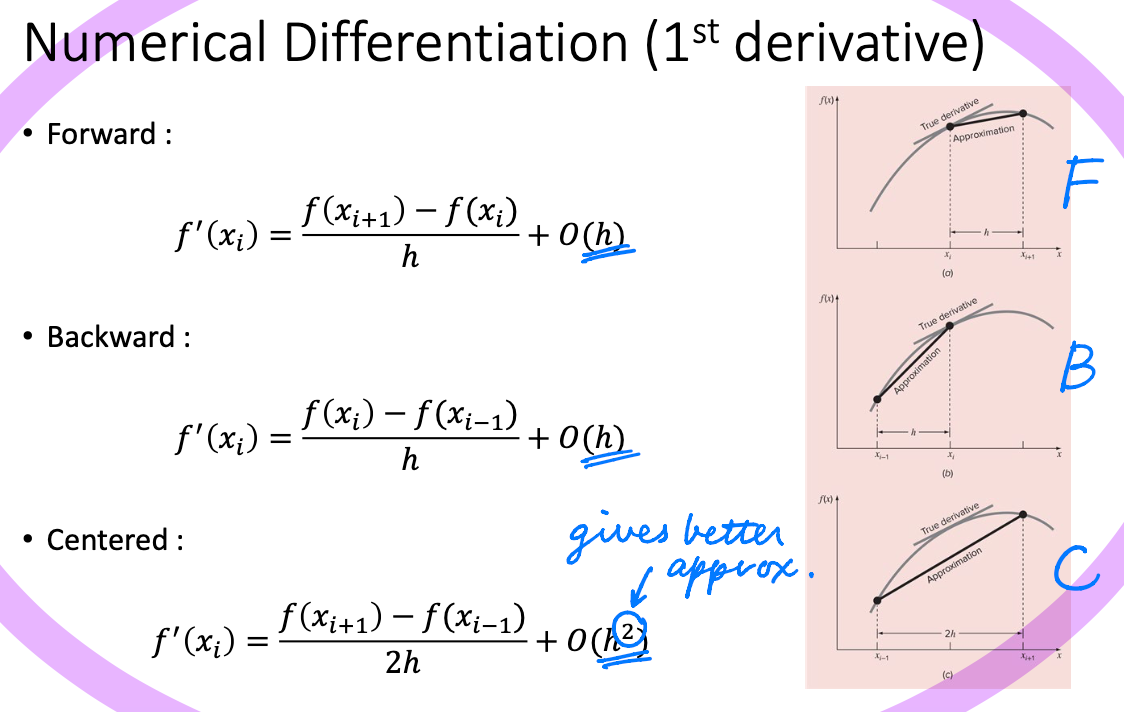   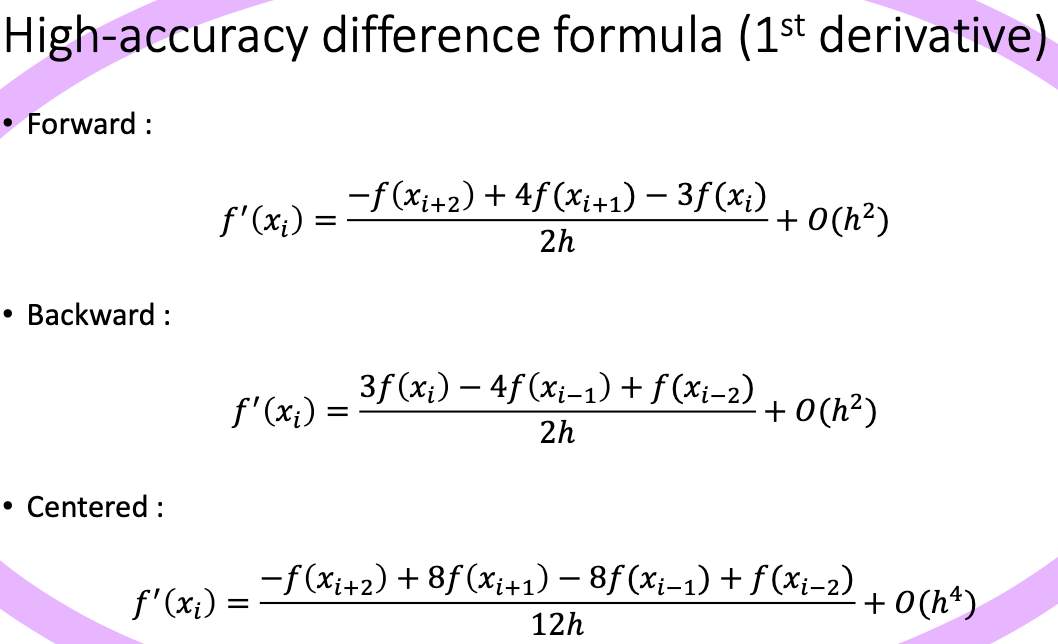

f = @(x) sin(x);
dx = @(x) cos(x);
xtest = pi/4;
h = pi/12;

Dtrue = dx(xtest)

% NUMERICAL DIFFERENTIATION
Dnf = (f(xtest + h) - f(xtest)) / h                                                     % forward
Dnb = (f(xtest) - f(xtest - h)) / h                                                     % backward
Dnc = (f(xtest + h) - f(xtest - h)) / (2*h)                                             % centered
                    
% HIGH-ACCURACY                 
Dhf = (-f(xtest + (2*h)) + 4*f(xtest + h) - 3*f(xtest)) / (2*h)                         % forward
Dhb = (3*f(xtest) - 4*f(xtest - h) + f(xtest - (2*h))) / (2*h)                          % backward
Dhc = (-f(xtest + (2*h)) + 8*f(xtest + h) - 8*f(xtest - h) + f(xtest - (2*h))) / (12*h) % centered

for i = [Dnf Dnb Dnc Dhf Dhb Dhc]
    err = abs(((Dtrue - i) / Dtrue) * 100);
    fprintf("%.4f | err = %.4f\n", i, err)
end

## Q4 [CORRECT]

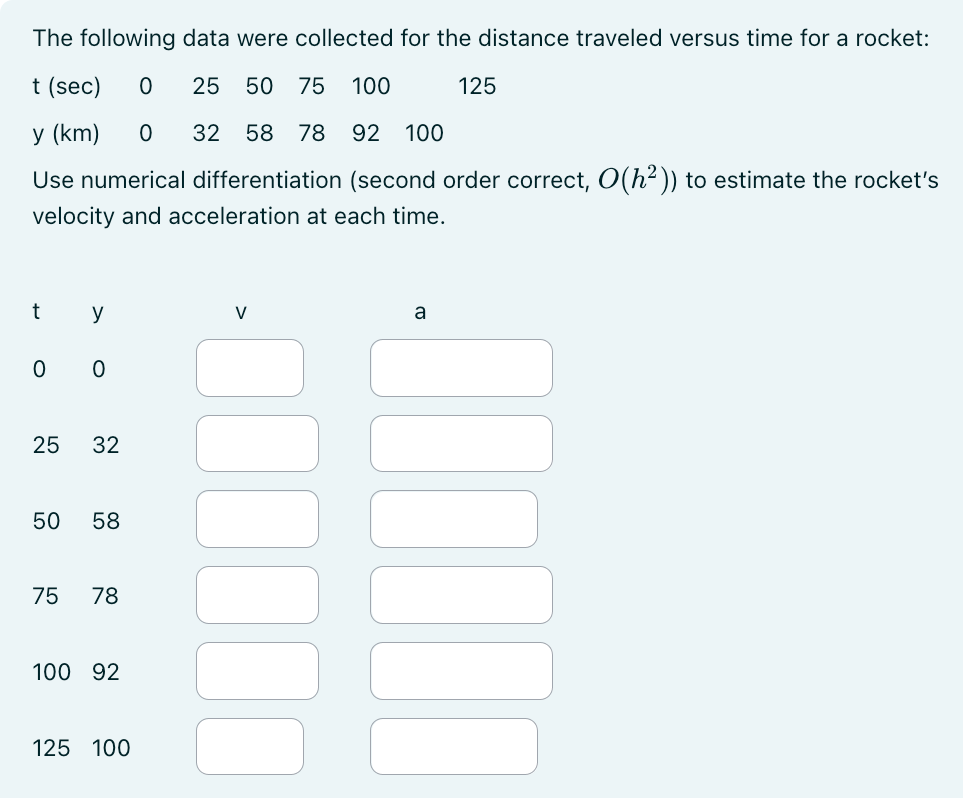

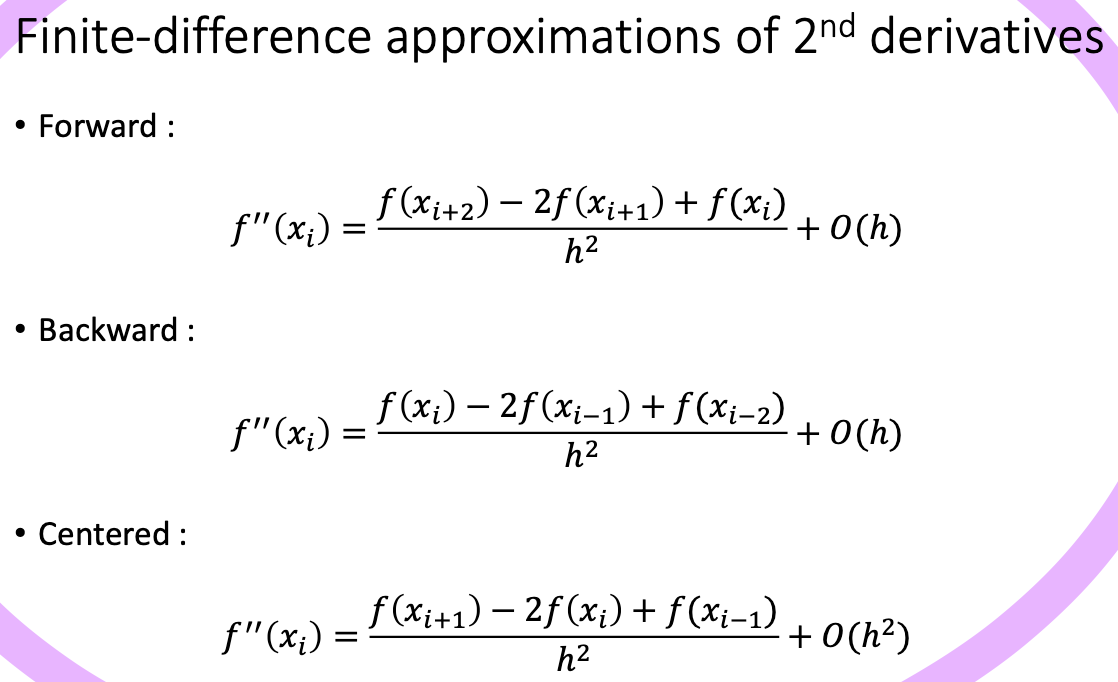

t = [0 	25 	50 	75 	100 125];
y = [0 	32 	58 	78 	92 	100];

h = 25; % compute step sizes from t (x-axis)

% CENTER
% for the inbetween data points
% do not do "±h" as it'll definitely go out of bounds
% start the loop from the second index and stop at second-last
% otherwise it'll cause vector index out of bounds
for i = 2 : length(t) - 1
    front = y(i+1);
    back = y(i-1);
    curr = y(i);
    ncv = (front - back) / (2*h); % numerical differentiation
    fca = (front - 2*curr + back) / (h^2); % finite-difference approximation
    fprintf("Center\t| t = %d~%d\t| v = %.4f | a = %.4f\n", back, front, ncv, fca)
end

Center	| t = 0~58	| v = 1.1600 | a = -0.0096
Center	| t = 32~78	| v = 0.9200 | a = -0.0096
Center	| t = 58~92	| v = 0.6800 | a = -0.0096
Center	| t = 78~100	| v = 0.4400 | a = -0.0096



% FRONT
% for the first data point
k = 1;
hfv = (-y(k+2) + 4*y(k+1) - 3*y(k)) / (2*h); % high-accuracy
ffa = (y(k+2) - 2*y(k+1) + y(k)) / (h^2); % finite-difference approximation
fprintf("Front\t| v = %.4f | a = %.4f\n", hfv, ffa)

Front	| v = 1.4000 | a = -0.0096



% BACK
% for the last data point
k = length(t);
hbv = (3*y(k) - 4*y(k-1) + y(k-2)) / (2*h); % high-accuracy
fba = (front - 2*curr + back) / (h^2); % finite-difference approximation
fprintf("Back\t| v = %.4f | a = %.4f\n", hbv, fba)

Back	| v = 0.2000 | a = -0.0096


## Q5 [CORRECT]

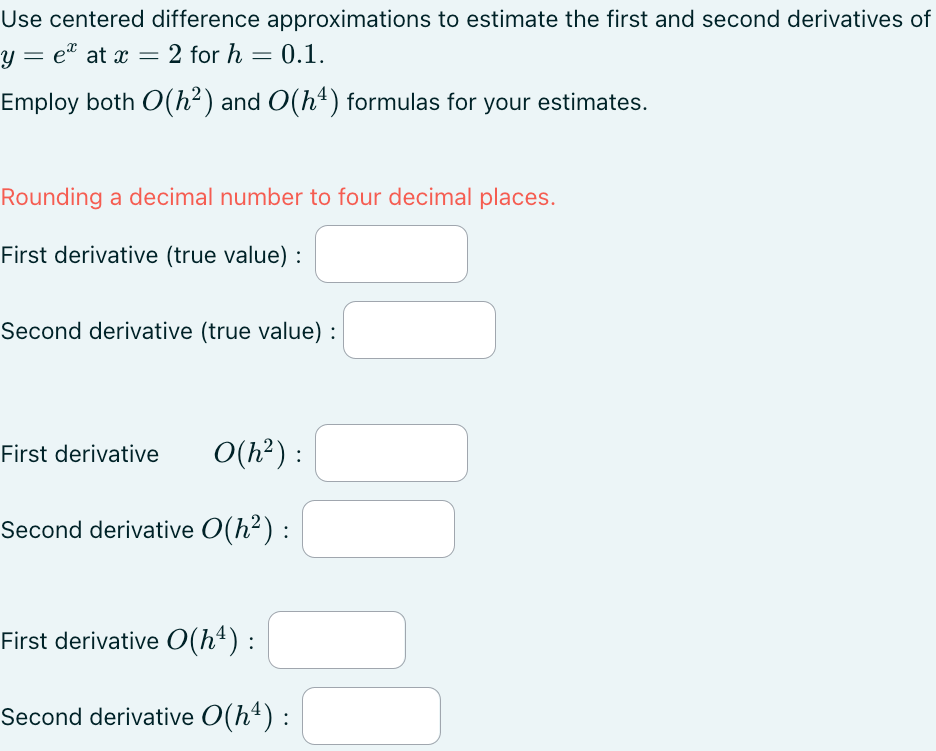

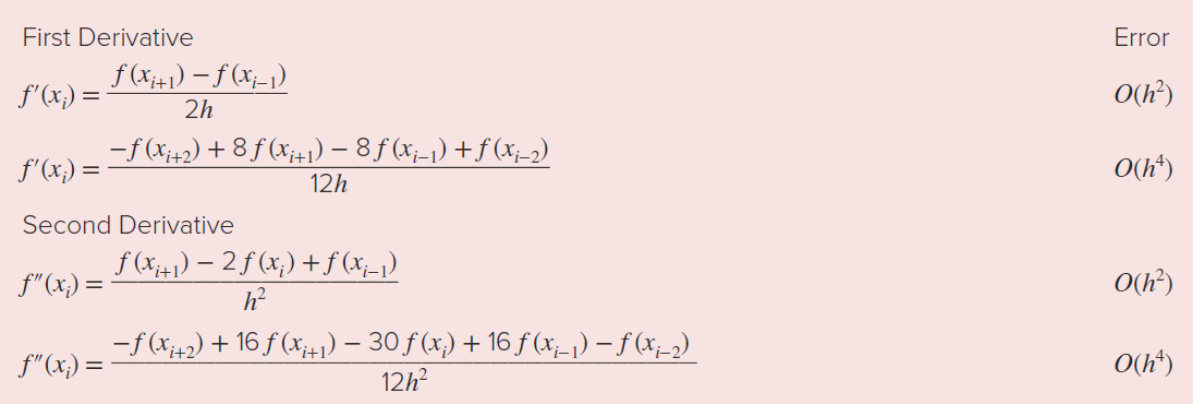

f = @(x) exp(x);
xtest = 2;
h = 0.1;

Dtrue = exp(xtest)

Dtrue = 7.3891


fdh2 = (f(xtest+h) - f(xtest-h)) / (2*h)

fdh2 = 7.4014

fddh2 = (f(xtest+h) - 2*f(xtest) + f(xtest-h)) / (h^2)

fddh2 = 7.3952


fdh4 = (-f(xtest+(2*h)) + 8*f(xtest+h) - 8*f(xtest-h) + f(xtest-(2*h))) / (12*h)

fdh4 = 7.3890

fddh4 = (-f(xtest+(2*h)) + 16*f(xtest+h) - 30*f(xtest) + 16*f(xtest-h) - f(xtest-(2*h))) / (12*(h^2))

fddh4 = 7.3890